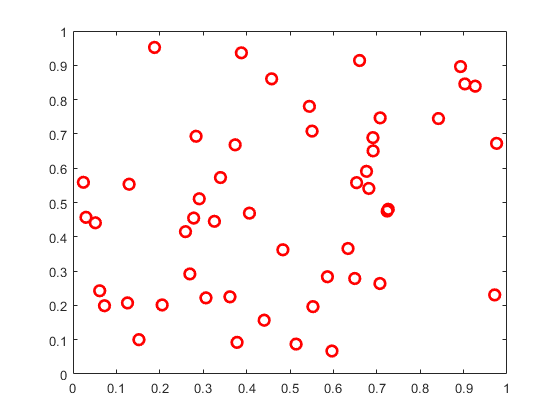

clc;
clf;
clear;

rng(3, 'twister');
cities = rand(2,50);
plot(cities(1, :), cities(2, :), 'ro', 'MarkerSize', 8, 'LineWidth',2);

save("50_cities.mat", "cities");

load("50_cities.mat")
temprature = 1e4;
temprature_min = 1e-6;
episodes = 20;
episode_length = 1e5;

multi_swap = 1;
trajectory_old = cities;
tic;
[trajectory_new, dist, temprature, exit_flag] = solveTSP(trajectory_old, temprature, temprature_min, episodes, episode_length, multi_swap);
toc;

历时 28.234865 秒。


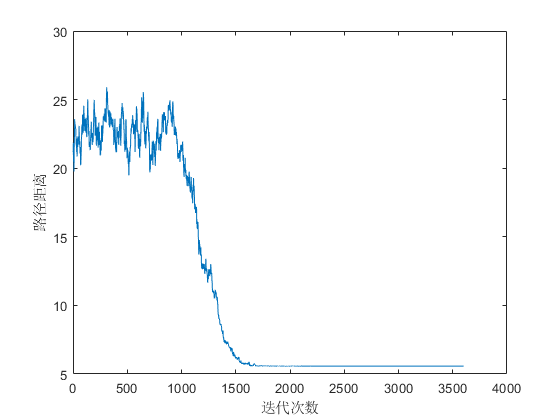

clf;
plot(dist);
xlabel('迭代次数');
ylabel('路径距离');

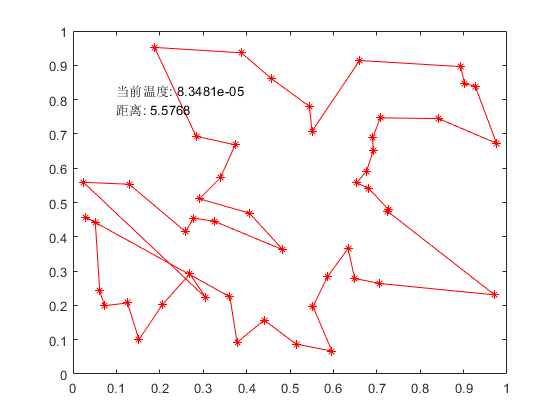


clf;
plot_trajectory(trajectory_new);
hold on;
text(0.1, 0.8, {['当前温度: ', num2str(temprature)];['距离: ', num2str(dist(end))]});

save("50_results.mat", "trajectory_new");

load x500.mat;

temprature = 1e6;
temprature_min = 1e-16;
episodes = 1e2;
episode_length = 1e7;
multi_swap = 2;
trajectory_old = cityXY;
tic;
[trajectory_new, dist, temprature, exit_flag] = solveTSP(trajectory_old, temprature, temprature_min, episodes, episode_length, multi_swap);
toc;

历时 30899.348664 秒。


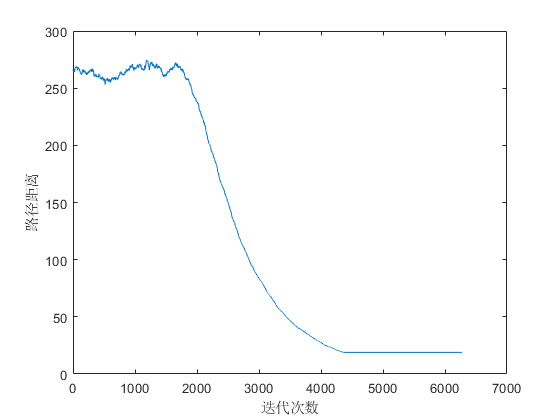

clf;
plot(dist);
xlabel('迭代次数');
ylabel('路径距离');

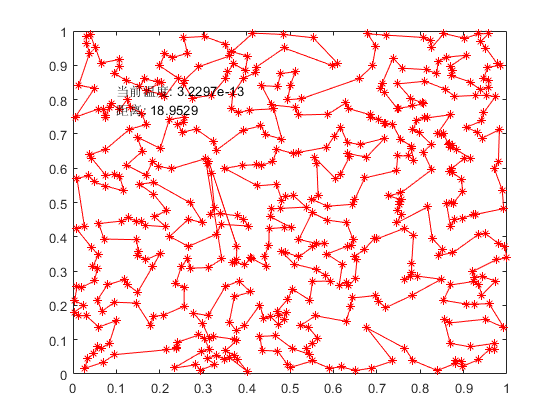


clf;
plot_trajectory(trajectory_new);
hold on;
text(0.1, 0.8, {['当前温度: ', num2str(temprature)];['距离: ', num2str(dist(end))]});

save("500_results.mat", "trajectory_new");
